# **ACM/IDS 104 - Problem Set 4 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## Problem 3 (10 points) Application of Least Squares to Data Fitting

The dataset $\texttt{carbig}$, a built-in MATLAB dataset, contains various characteristics for $m=406$ automobiles from the 1970s and 1980s. Let $x_1, \, x_2$ and $y$ be the $\texttt{Weight}$, $\texttt{Horsepower}$ and $\texttt{MPG (Miles Per Gallon)}$ respectively. Let us assume the following theoretical model for the data:


$$y = f(x_1, x_2) = \beta_0+\beta_1x_1+\beta_2x_2+\beta_3x_1x_2\,\,\,\,\,(\star)$$


Let $\beta^* = \left(\beta_0^*, \beta_1^*, \beta_2^*, \beta_3^*\right)^T$ denote the best fit to the data, i.e. the vector that minimizes the Euclidean norm of the residual vector $r = \left(r_1,\cdots,r_m\right)^T$, where:


$$r_i = y^{(i)}-f\left(x_1^{(i)}, x_2^{(i)}\right)$$


## Part (a) (5 points)

Derive the system of normal equations on $\beta^*$. Do this in your written-up solutions.

## Part (b) (5 points)

Find $\beta^*$ by solving the normal system numerically and plot the scatter plot of the data $\left\{\left(x_1^{(i)}, x_2^{(i)}, y^{(i)}\right)\right\}, i = 1\cdots m$, together with the fitted surface $y=f\left(x_1, x_2\right)$ given by $(\star)$.

To start, let us load the dataset, define our variables, and perform some necessary cleanup as there exist $\texttt{NaN}$ values. We do this for you :)

load carbig;
x1=Weight;
x2=Horsepower;
y=MPG;
clearvars -except x1 x2 y;
% Data cleaning
y=y(x1>0);
x2=x2(x1>0);
x1=x1(x1>0);

y=y(x2>0);
x1=x1(x2>0);
x2=x2(x2>0);

x1=x1(y>0);
x2=x2(y>0);
y=y(y>0);

Now, the dataset is ready for you to solve the normal system. Let us vizualize it. Drag the 3D plot around to get a better sense of the data.

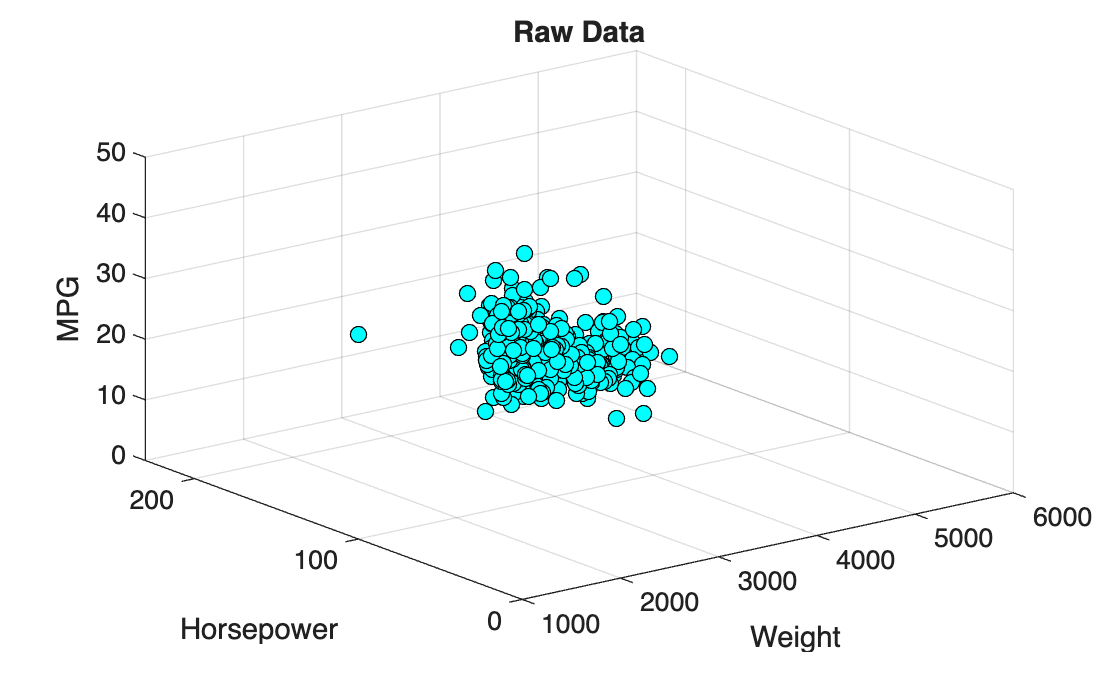

figure;
scatter3(x1,x2,y,'MarkerEdgeColor','k','MarkerFaceColor','c');
xlabel('Weight');
ylabel('Horsepower');
zlabel('MPG');
title('Raw Data');

Finally, let us find the best surface to fit the data. Remember, in MATLAB, when solving a system, backslash is your best friend. Use $\texttt{scatter3()}$ and $\texttt{fsurf()}$ when plotting.

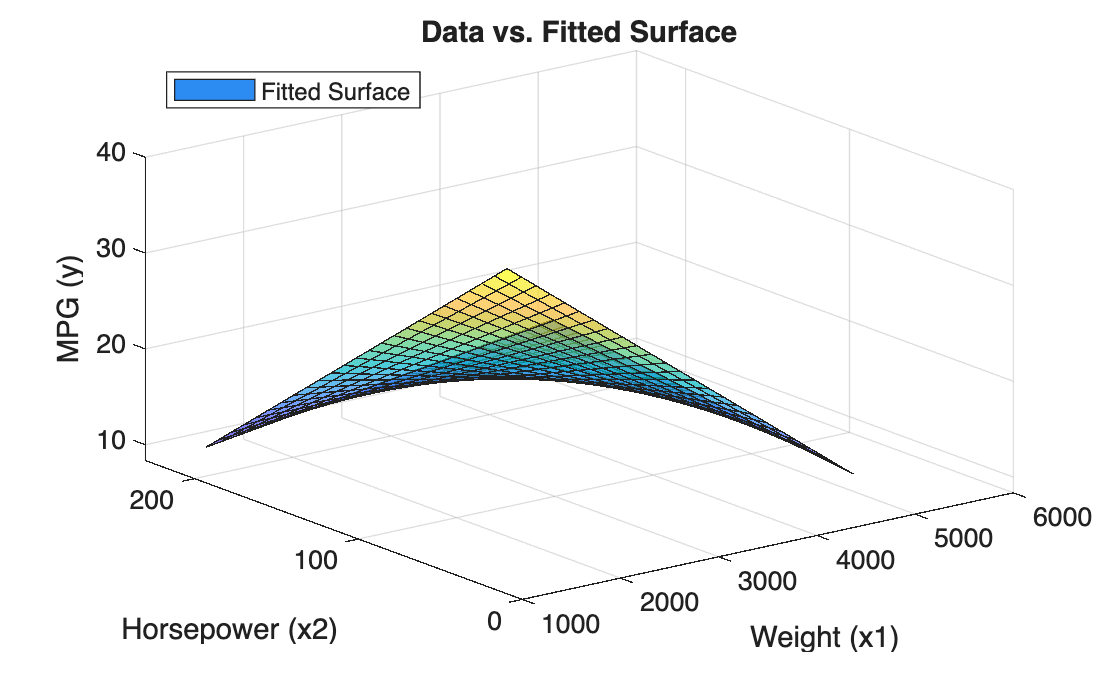

%{
Build the matrix A
Solve for beta
%}

% num of data points in m
m = length(y);

% A has columns [1, x1, x2, x1*x2]
A = [ones(m, 1), x1, x2, x1 .* x2];

% find least squares solution B* that minimizes norm(A*beta - y).
beta = A \ y;

%{
Plotting    
%}
figure;

% grid of points spanning the range of x1 and x2
x1_fit = linspace(min(x1), max(x1), 25);
x2_fit = linspace(min(x2), max(x2), 25);
[X1_fit, X2_fit] = meshgrid(x1_fit, x2_fit);

% fitted y values on grid
Y_fit = beta(1) + beta(2) * X1_fit + beta(3) * X2_fit + beta(4) * (X1_fit .* X2_fit);

surf(X1_fit, X2_fit, Y_fit, 'FaceAlpha', 0.7, 'DisplayName', 'Fitted Surface');

xlabel('Weight (x1)');
ylabel('Horsepower (x2)');
zlabel('MPG (y)');
title('Data vs. Fitted Surface');
legend('Location', 'northwest');
grid on;
hold off;

## Problem 4 (10 points) Polynomial Interpolation

Interpolating polynomials $p(x)$ are used for approximation of complex functions $g(x)$. Intuitively, the larger the degree of the interpolating polynomial, the more accurate the approximation $g(x)\approx p(x),x\in [a,b]$. Generally, this is not true (as you will see in this problem). High degree interpolating polynomials often behave badly, especially near the ends of the interval $[a,b]$. In practice, piecewise cubic splines are often used instead of high degree polynomials.

Suppose we want to approximate the function:


$$g(x) = \frac{\cos x}{\cosh x},\,\,x\in[-a,a]$$


using $n$ points equally spaced between $-a$ and $a$. Find the interpolating polynomials and plot them versus the function $g(x)$ for $a = 1, 5$ and $n = 3, 5, 10, 15$. In your plot, show also the data points used for interpolation. The code should produce a single figure with 8 subplots.

Useful MATLAB functions for this problem:


$$\texttt{linspace(), fplot(), polyval(), polyfit()}$$


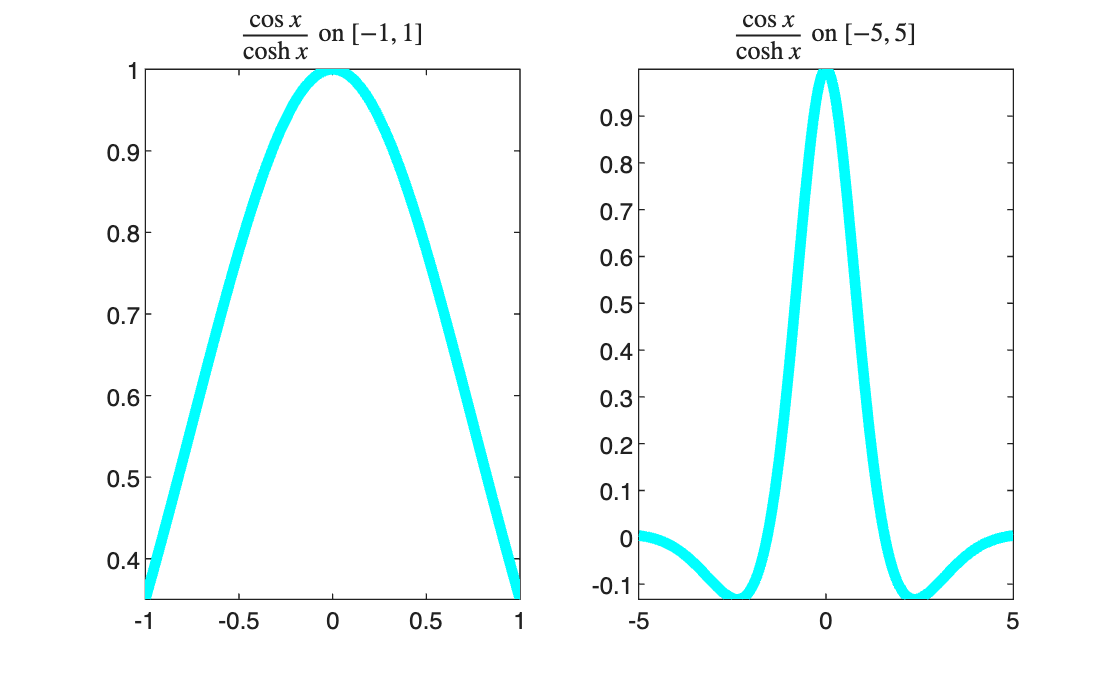

%{
Let us start by doing some setup
%}
g = @(x) cos(x) ./ cosh(x); % you can define functions like this
a = [1, 5]; % setting interval values
n = [3, 5, 10, 15]; % setting the number of points
sub = 1; % setting the subplot index

%{
Let us see how g(x) looks like on both intervals
%}
figure;
subplot(1, 2, 1);
fplot(g, [-a(1), a(1)], "-c", "lineWidth", 4);
title("$\frac{\cos{x}}{\cosh{x}}$ on $[-1, 1]$","Interpreter","latex");
hold on
subplot(1, 2, 2);
fplot(g, [-a(2), a(2)], "-c", "lineWidth", 4);
title("$\frac{\cos{x}}{\cosh{x}}$ on $[-5, 5]$","Interpreter","latex");

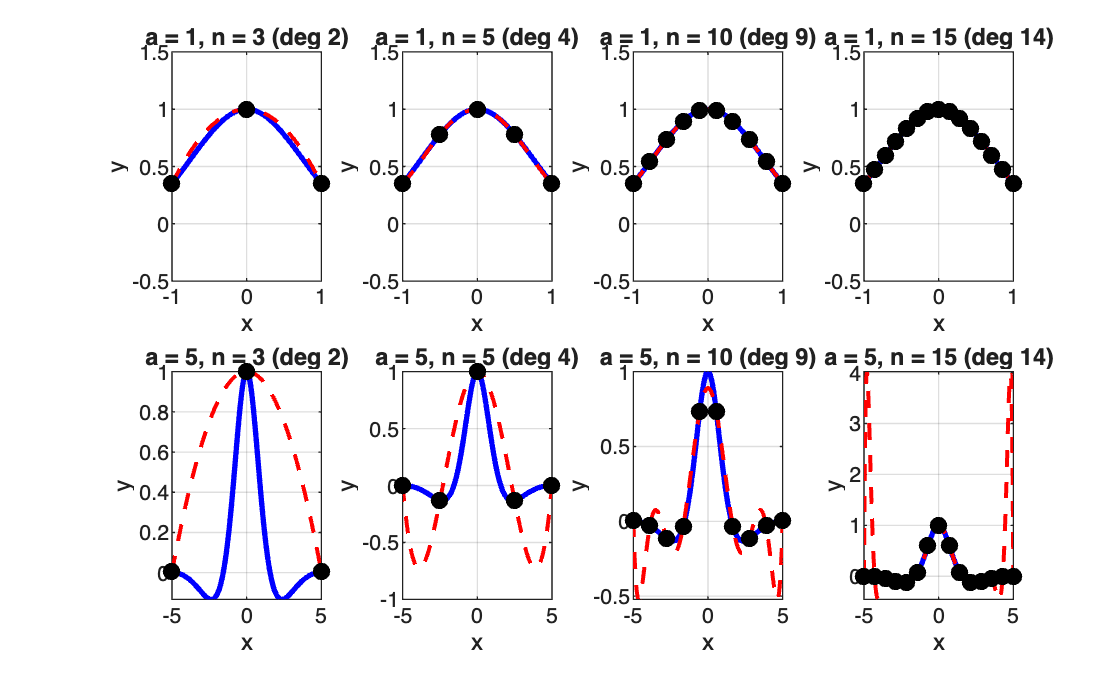


%{
Complete the nested for-loops
%}
figure;
for ival = a
    for degree = n-1
        n_points = degree + 1;
        subplot(2, 4, sub);

        %{
        Select degree+1 points in the interval
        Evaluate g(x) on these points
        Find the polynomial coefficients
        %}

        x_points = linspace(-ival, ival, n_points);
        y_points = g(x_points);

        p_coeffs = polyfit(x_points, y_points, degree);
        
        %{ 
        PLOTTING
        Plot g(x), the sampled points and interpolating polynomial
        Please use different colors and linestyles
        %}

        x_fine = linspace(-ival, ival, 200);
        
        plot(x_fine, g(x_fine), 'b-', 'LineWidth', 2);
        
        hold on;
        
        y_poly = polyval(p_coeffs, x_fine);
        plot(x_fine, y_poly, 'r--', 'LineWidth', 1.5);
        
        plot(x_points, y_points, 'ko', 'MarkerFaceColor', 'k');
        
        title(['a = ' num2str(ival) ', n = ' num2str(n_points) ' (deg ' num2str(degree) ')']);
        xlabel('x');
        ylabel('y');
        
        if ival == 1
            ylim([-0.5, 1.5]);
        else
            ylim('auto');
        end
        
        grid on;
        hold off;
        
        sub = sub + 1;
        
    end
end

## Problem 5 (10 points) Stability of the Gram-Schmidt Algorithm

The classical Gram-Schmidt algorithm is numerically unstable. This means that, when implemented on a computer, the round-off errors can cause the output vectors to be significantly non-orthogonal. To explore the issue, perform the following computations for each $n = 10, 20, 30,\cdots, 100$:

- Create the Hilbert matrix $H_n$ of size $n$ (using $\texttt{hilb(n)}$) and consider the columns $h_1,\cdots,h_n$ as a basis of $\mathbb{R}^n$. The matrix $H_n$ is non-singular, and thus its columns indeed form a basis, but it is very close to singular (i.e. its columns are close to being linearly dependent), and this leads to numerical problems.

- Implement the basic Gram-Schmidt algorithm to construct an orthogonal basis $\{v_1,\cdots,v_n\}$ of $\mathbb{R}^n$ from $h_1,\cdots,h_n$. Please don't use any advanced built-in function for orthogonalization (such as $\texttt{orthog()}$) just basic matrix operations. At the end of the process normalize your vectors so that the basis is orthonormal.

- If vectors $v_1,\cdots,v_n$ obtained in (2) are orthonormal, then $V = [v_1,\cdots,v_n]$ must be orthogonal. As a measure of orthogonality, compute the infinite norm $\delta_V(n) = ||I_n-V^TV||_{\infty}$, which is a matrix norm (use $\texttt{norm(A, Inf)}$). The closer $\delta_V(n)$ is to zero, the closer the columns of $V$ are to being orthogonal.

- Repeat (2) and (3) to construct an orthonormal basis $\{u_1,\cdots,u_n\}$ using the modified Gram-Schmidt algorithm (which is numerically more stable) described in lecture 9 (page 46), and compute $\delta_U(n)$.

- To compare the basic and modified Gram-Schmidt algorithms, plot $\delta_V(n)$ and $\delta_U(n)$ versus $n$.

%{
Complete the following for-loop following (1)-(4)
%}
n_values = 10:10:100;
delta_V = zeros(size(n_values));
delta_U = zeros(size(n_values));
idx = 1;

for n=10:10:100
    H = hilb(n);
    V = zeros(n, n);

    for j = 1:n
        % jth col of H
        v_j = H(:, j);
        
        % orthogonalize
        for i = 1:(j-1)
            v_j = v_j - (V(:, i)' * H(:, j)) * V(:, i);
        end
        
        % normalize
        V(:, j) = v_j / norm(v_j);
    end

    %% orthogonality measure for GS
    I_n = eye(n);
    delta_V(idx) = norm(I_n - V' * V, Inf);

    % stors orthonormal vectors
    U = zeros(n, n);

    for j = 1:n
        u_j = H(:, j);
        
        % orthogonalize; project against the updated u_j here instead
        for i = 1:(j-1)
            u_j = u_j - (U(:, i)' * u_j) * U(:, i);
        end
        
        % normalize
        U(:, j) = u_j / norm(u_j);
    end
    
    delta_U(idx) = norm(I_n - U' * U, Inf);


n =  10: δ_V = 2.8816e+00, δ_U = 1.1675e-04
n =  20: δ_V = 1.3000e+01, δ_U = 2.3324e+00
n =  30: δ_V = 2.2263e+01, δ_U = 3.3172e+00
n =  40: δ_V = 3.2915e+01, δ_U = 3.4510e+00
n =  50: δ_V = 4.2885e+01, δ_U = 4.6494e+00
n =  60: δ_V = 5.2317e+01, δ_U = 5.4218e+00
n =  70: δ_V = 6.2538e+01, δ_U = 5.3499e+00
n =  80: δ_V = 4.9000e+01, δ_U = 6.4467e+00
n =  90: δ_V = 8.2084e+01, δ_U = 6.8704e+00
n = 100: δ_V = 9.2175e+01, δ_U = 7.1246e+00


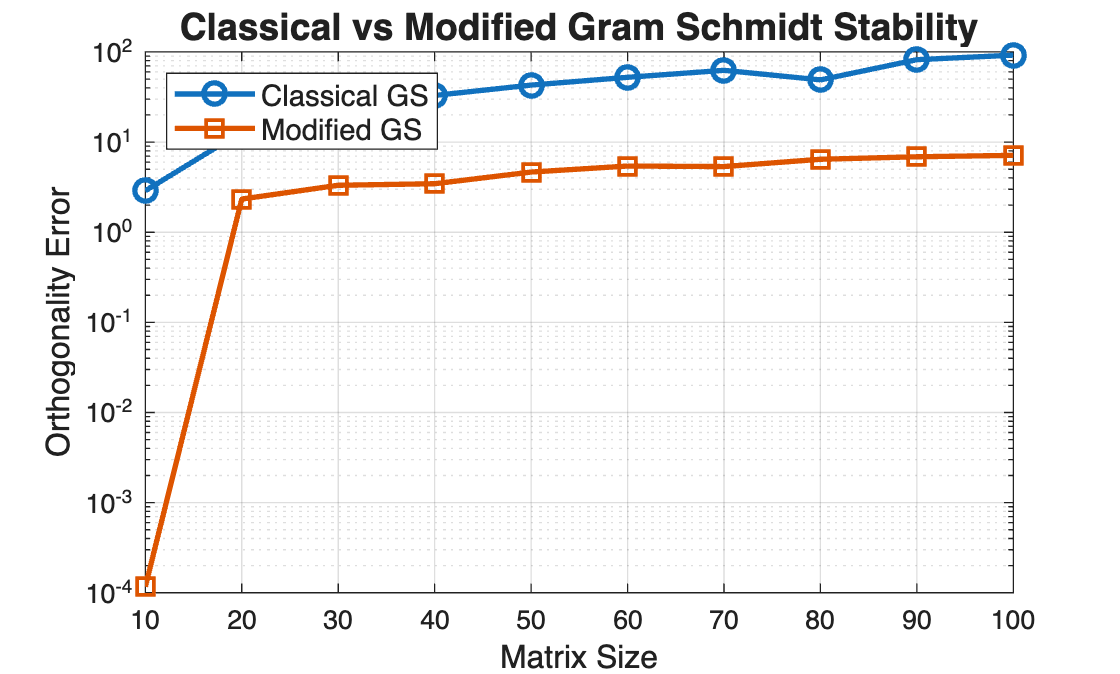

    fprintf('n = %3d: δ_V = %.4e, δ_U = %.4e\n', n, delta_V(idx), delta_U(idx));

    idx = idx + 1;
end

%{
Visualize the comparison as specified in (5)
%}
figure;
semilogy(n_values, delta_V, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Classical GS');
hold on;
semilogy(n_values, delta_U, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Modified GS');
hold off;

xlabel('Matrix Size', 'FontSize', 12);

ylabel('Orthogonality Error', 'FontSize', 12);
title('Classical vs Modified Gram Schmidt Stability', 'FontSize', 14);
legend('Location', 'northwest', 'FontSize', 11);
grid on;

% Classical GS is numerically unstable
% Modified GS is more stable